1. Generating binary sequence and rectangular pulses

L=1000;
bs=randi([0 1],1,L);
A=1;
S=-A+(2*A).*bs;

2. Generate AWGN sequence 

u = 0;
sigma = 1;
N = u + sigma*randn(1,L);

3. Generate Recieved Signal

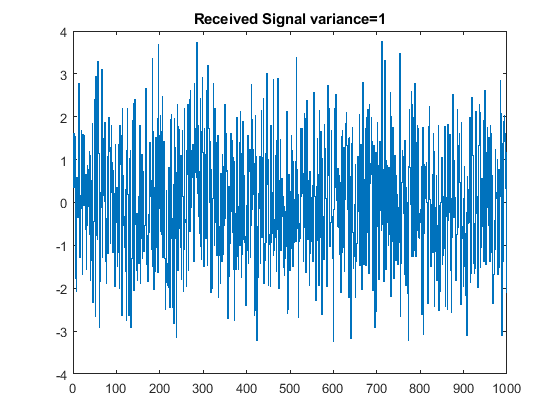

R = S + N;
stairs(R);
title("Received Signal variance=1");

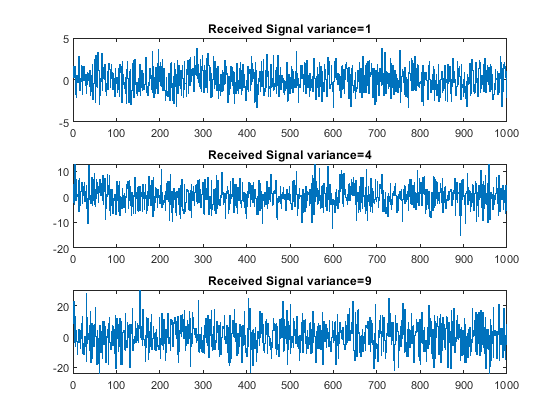


%variance=4
sigma2 = 4 ;
N2 = u + sigma2* randn(1,L);
R2 = S + N2  ; 

%variance=9
sigma3 = 9 ;
N3 = u + sigma3* randn(1,L);
R3 = S + N3 ;

%plotting the graphs
figure;
subplot(3,1,1);
stairs(R);
title("Received Signal variance=1");

subplot(3,1,2);
stairs(R2);
title("Received Signal variance=4");

subplot(3,1,3);
stairs(R3);
title("Received Signal variance=9");

It is clearly visible that when variance increases, the amplitude of the recieved signal also increases

4.  Comparison of decoded signal with transmitted signal 

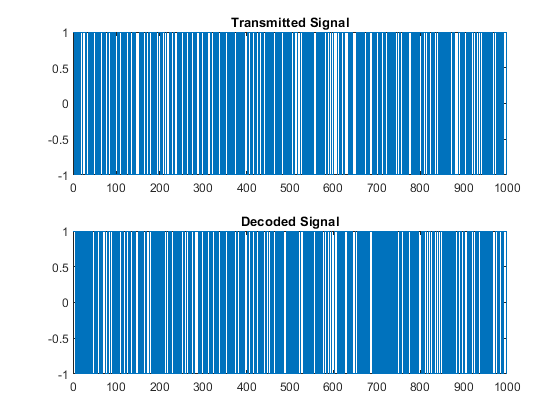

tau=0;
Y = zeros(1,L);
for j = 1:L
    if R(j) > tau
        Y(j) = A;
    else
        Y(j) = -1*A;
    end
end
figure;
subplot(2,1,1);
stairs(S);
title("Transmitted Signal");

subplot(2,1,2);
stairs(Y);
title("Decoded Signal");

It is hard to observe any differences in this scale. By zooming in x axis

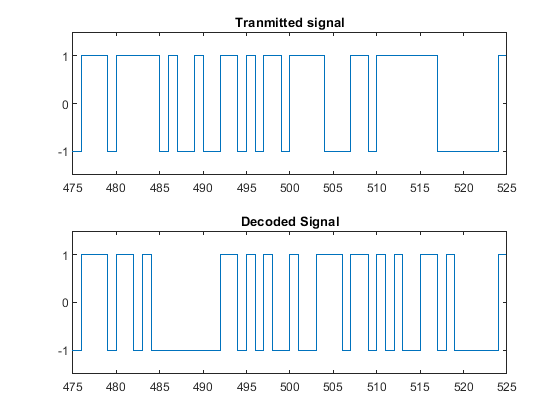

figure;
subplot(2,1,1);
stairs(S);
axis([475 525 -1.5 1.5]);
title("Tranmitted signal");

subplot(2,1,2);
stairs(Y);
axis([475 525 -1.5 1.5]);
title("Decoded Signal");

We can see that there are some error bits in the recieved signal but most of the bits are decoded correctly